## Upload the big dataset (>250MB) to MATLAB Drive and read table

BitcoinData = readtable('bitcoin-dataset.csv');

Tablesize = size(BitcoinData)

Tablesize =      4857377           8


head(BitcoinData,1)

ans = 1×8 table
    Timestamp     Open    High    Low     Close    Volume__BTC_    Volume__Currency_    Weighted_Price
    __________    ____    ____    ____    _____    ____________    _________________    ______________

    1.3253e+09    4.39    4.39    4.39    4.39       0.45558               2                 4.39     


## Convert timestamp

datetest = BitcoinData(:,1);
datetest = table2array(datetest);
BitcoinData.Timestamp = datetime(datetest, 'ConvertFrom', 'posixtime');

## Remove NaNs

% how many NaNs in each column
NaN2 = sum(isnan(BitcoinData.Open));
NaN3 = sum(isnan(BitcoinData.High));
NaN4 = sum(isnan(BitcoinData.Low));
NaN5 = sum(isnan(BitcoinData.Close));
NaN6 = sum(isnan(BitcoinData.Volume__BTC_));
NaN7 = sum(isnan(BitcoinData.Volume__Currency_));
NaN8 = sum(isnan(BitcoinData.Weighted_Price));

% remove NaNs
BitcoinData = BitcoinData(isnan(BitcoinData.High) == 0,:);

## Select data

BitcoinDataTimetable = table2timetable(BitcoinData);

% March 2013
% S = timerange('17-Mar-2013 00:00:00','18-Mar-2013 23:59:00'); %2days
% S = timerange('17-Mar-2013 00:00:00','23-Mar-2013 23:59:00'); %7days
% S = timerange('17-Mar-2013 00:00:00','30-Mar-2013 23:59:00'); %14days

% March 2016
% S = timerange('17-Mar-2016 00:00:00','18-Mar-2016 23:59:00'); %2days
% S = timerange('17-Mar-2016 00:00:00','23-Mar-2016 23:59:00'); %7days
% S = timerange('17-Mar-2016 00:00:00','30-Mar-2016 23:59:00'); %14days

% March 2019
% S = timerange('17-Mar-2019 00:00:00','18-Mar-2019 23:59:00'); %2days
% S = timerange('17-Mar-2019 00:00:00','23-Mar-2019 23:59:00'); %7days
% S = timerange('17-Mar-2019 00:00:00','30-Mar-2019 23:59:00'); %14days

% March 2021

% S = timerange('17-Mar-2021 00:00:00','18-Mar-2021 23:59:00'); %2days
% S = timerange('17-Mar-2021 00:00:00','23-Mar-2021 23:59:00'); %7days
S = timerange('17-Mar-2021 00:00:00','30-Mar-2021 23:59:00'); %14days

BitcoinData2 = BitcoinDataTimetable(S,:);
Tablesize = size(BitcoinData2)

Tablesize =        20108           7


## Calculate price change

yconvert = diff(BitcoinData2.Close)

yconvert =    22.0000
  -45.7500
    4.8500
 -103.7700
  -79.3100
  -21.0600
  -49.2400
   85.5200
   23.2700
  -28.8300


% need to drop the top row 
xconvert = BitcoinData2{[2:end], [1:3 5:7]};

## Find ups and downs

Ysvm = double(yconvert >= 0) % Response data

Ysvm =      1
     0
     1
     0
     0
     0
     0
     1
     1
     0


sum(Ysvm)

ans = 9928

## Create model - preprocessing

% standardization, and Initial predictor set (matrix)

Xsvm = zscore(xconvert);

BitcoinData_new = [Xsvm, Ysvm];

## Split dataset into training and testing data

PD = 0.20;
cv = cvpartition(size(BitcoinData_new,1),'HoldOut',PD);
Xtrain = BitcoinData_new(cv.training,[1:end - 1]);
Ytrain = BitcoinData_new(cv.training,end);
Xtest = BitcoinData_new(cv.test,[1:end - 1]);
Ytest = BitcoinData_new(cv.test,end);
size(Xtrain)

ans =        16086           6



Xtrain = zscore(Xtrain);
Xtest = zscore(Xtest); % To be more precise, this zscore should be calculated using the mean of the training data. Improvement can be made for further studies. 

## SVM model with training-testing split

% svmModel = fitcsvm(Xtrain, Ytrain, 'BoxConstraint', 100, 'KernelScale', 1,"KernelFunction","rbf")

% numSV1 = size(svmModel.SupportVectors,1)

% CVSVMModel = crossval(svmModel)
% classLoss = kfoldLoss(CVSVMModel)

## Train SVM Model with Kernel Scales

Collect_F = [];     Collect_R = [];     Collect_P = [];     Collect_A = [];
KS = [0.1, 0.5, 3]; %100
for i = KS
    disp(['KS = ' num2str(i)])
    SVM = fitcsvm(Xtrain,Ytrain, 'KernelFunction', 'rbf', 'KernelScale', i, 'BoxConstraint', 1);
    [labels score] = predict(SVM, Xtest);
    numSV = size(SVM.SupportVectors,1)
    [ClassPerformance, OverallAccuracy] = CFM_Stats(Ytest, labels)
    Collect_F = [Collect_F, ClassPerformance.Fscore];
    Collect_R = [Collect_R, ClassPerformance.Fscore];
    Collect_P = [Collect_P, ClassPerformance.Fscore];
    Collect_A = [Collect_A, OverallAccuracy];

end

KS = 0.1


numSV = 13903

Confusion Matrix:
        1433         587
         732        1269

Overall accuracy = 0.67197


ClassPerformance = 2×6 table
    accuracy    precision    recall     Fscore     sensitivity    specificity
    ________    _________    _______    _______    ___________    ___________

    0.67197      0.66189     0.70941    0.68483      0.70941        0.63418  
    0.67197      0.68373     0.63418    0.65802      0.63418        0.70941  


OverallAccuracy = 0.6720

KS = 0.5


numSV = 14830

Confusion Matrix:
        1575         445
         717        1284

Overall accuracy = 0.71102


ClassPerformance = 2×6 table
    accuracy    precision    recall     Fscore     sensitivity    specificity
    ________    _________    _______    _______    ___________    ___________

    0.71102      0.68717      0.7797    0.73052       0.7797        0.64168  
    0.71102      0.74263     0.64168    0.68847      0.64168         0.7797  


OverallAccuracy = 0.7110

KS = 3


numSV = 15816

Confusion Matrix:
        1904         116
        1792         209

Overall accuracy = 0.52549


ClassPerformance = 2×6 table
    accuracy    precision    recall     Fscore     sensitivity    specificity
    ________    _________    _______    _______    ___________    ___________

    0.52549      0.51515     0.94257     0.6662      0.94257        0.10445  
    0.52549      0.64308     0.10445    0.17971      0.10445        0.94257  


OverallAccuracy = 0.5255

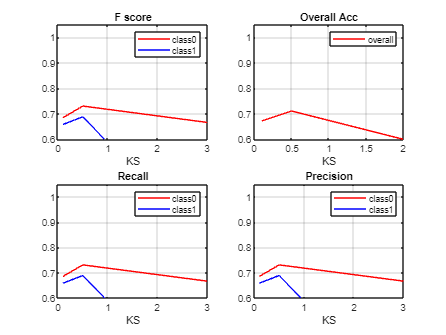


figure,
subplot(2,2,1), plot(KS, Collect_F(1, :), 'r', KS, Collect_F(2, :), 'b'),
title('F score'), grid on, ylim([0.6, 1.05]), legend({'class0', 'class1'}), xlabel('KS')
subplot(2,2,2), plot(KS, Collect_A(1, :), 'r'),
title('Overall Acc'), grid on, ylim([0.6, 1.05]), legend({'overall'}), xlabel('KS')
subplot(2,2,3), plot(KS, Collect_R(1, :), 'r', KS, Collect_R(2, :), 'b'),
title('Recall'), grid on, ylim([0.6, 1.05]), legend({'class0', 'class1'}), xlabel('KS')
subplot(2,2,4), plot(KS, Collect_P(1, :), 'r', KS, Collect_P(2, :), 'b'),
title('Precision'), grid on, ylim([0.6, 1.05]), legend({'class0', 'class1'}), xlabel('KS')

## Train SVM Model with BoxConstraints

Collect_F = [];     Collect_R = [];     Collect_P = [];     Collect_A = [];       Collect_SV = [];
BoxCs = [0.1, 3, 5]; %100
for i = BoxCs
    disp(['BoxCs = ' num2str(i)])
    SVM = fitcsvm(Xtrain,Ytrain, 'KernelFunction', 'rbf', 'KernelScale', 1, 'BoxConstraint', i);
    [labels score] = predict(SVM, Xtest);
    numSV = size(SVM.SupportVectors,1)
    [ClassPerformance, OverallAccuracy] = CFM_Stats(Ytest, labels)
    Collect_F = [Collect_F, ClassPerformance.Fscore];
    Collect_R = [Collect_R, ClassPerformance.Fscore];
    Collect_P = [Collect_P, ClassPerformance.Fscore];
    Collect_A = [Collect_A, OverallAccuracy];
end

BoxCs = 0.1


numSV = 15873

Confusion Matrix:
        1977          43
        1937          64

Overall accuracy = 0.50759


ClassPerformance = 2×6 table
    accuracy    precision     recall      Fscore     sensitivity    specificity
    ________    _________    ________    ________    ___________    ___________

    0.50759      0.50511      0.97871     0.66633      0.97871       0.031984  
    0.50759      0.59813     0.031984    0.060721     0.031984        0.97871  


OverallAccuracy = 0.5076

BoxCs = 3


numSV = 13667

Confusion Matrix:
        1620         400
         516        1485

Overall accuracy = 0.7722


ClassPerformance = 2×6 table
    accuracy    precision    recall     Fscore     sensitivity    specificity
    ________    _________    _______    _______    ___________    ___________

     0.7722      0.75843     0.80198     0.7796      0.80198        0.74213  
     0.7722       0.7878     0.74213    0.76428      0.74213        0.80198  


OverallAccuracy = 0.7722

BoxCs = 5


numSV = 12577

Confusion Matrix:
        1629         391
         476        1525

Overall accuracy = 0.78438


ClassPerformance = 2×6 table
    accuracy    precision    recall     Fscore     sensitivity    specificity
    ________    _________    _______    _______    ___________    ___________

    0.78438      0.77387     0.80644    0.78982      0.80644        0.76212  
    0.78438      0.79593     0.76212    0.77866      0.76212        0.80644  


OverallAccuracy = 0.7844

BoxCs = 100


numSV = 8231

Confusion Matrix:
        1655         365
         433        1568

Overall accuracy = 0.80154


ClassPerformance = 2×6 table
    accuracy    precision    recall     Fscore     sensitivity    specificity
    ________    _________    _______    _______    ___________    ___________

    0.80154      0.79262     0.81931    0.80574      0.81931        0.78361  
    0.80154      0.81117     0.78361    0.79715      0.78361        0.81931  


OverallAccuracy = 0.8015

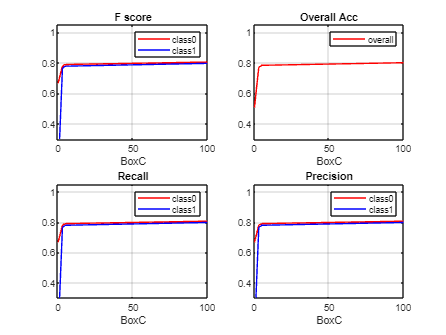


figure,
subplot(2,2,1), plot(BoxCs, Collect_F(1, :), 'r', BoxCs, Collect_F(2, :), 'b'),
title('F score'), grid on, ylim([0.3, 1.05]), legend({'class0', 'class1'}), xlabel('BoxC')
subplot(2,2,2), plot(BoxCs, Collect_A(1, :), 'r'),
title('Overall Acc'), grid on, ylim([0.3, 1.05]), legend({'overall'}), xlabel('BoxC')
subplot(2,2,3), plot(BoxCs, Collect_R(1, :), 'r', BoxCs, Collect_R(2, :), 'b'),
title('Recall'), grid on, ylim([0.3, 1.05]), legend({'class0', 'class1'}), xlabel('BoxC')
subplot(2,2,4), plot(BoxCs, Collect_P(1, :), 'r', BoxCs, Collect_P(2, :), 'b'),
title('Precision'), grid on, ylim([0.3, 1.05]), legend({'class0', 'class1'}), xlabel('BoxC')


return

SVM.Alpha
SVM.Beta

## Plots

## ROC - with Box Constraint – 5 ; Kernel Scale – 1.

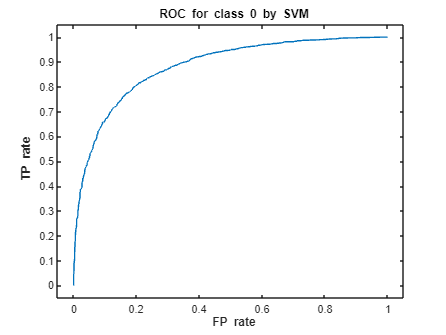

[Xcurve0, Ycurve0, T, AUC] = perfcurve(Ytest, score(:,1),0);
figure,
plot(Xcurve0, Ycurve0)
xlim([-0.05 1.05]), ylim([-0.05 1.05]), xlabel('\bf FP rate'), ylabel('\bf TP rate')
title('\bf ROC for class 0 by SVM')

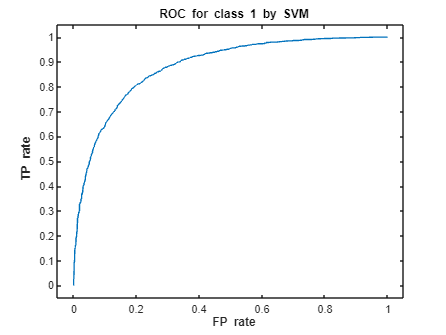


[Xcurve1, Ycurve1, T, AUC] = perfcurve(Ytest, score(:,2),1);
figure,
plot(Xcurve1, Ycurve1)
xlim([-0.05 1.05]), ylim([-0.05 1.05]), xlabel('\bf FP rate'),  ylabel('\bf TP rate')
title('\bf ROC for class 1 by SVM')